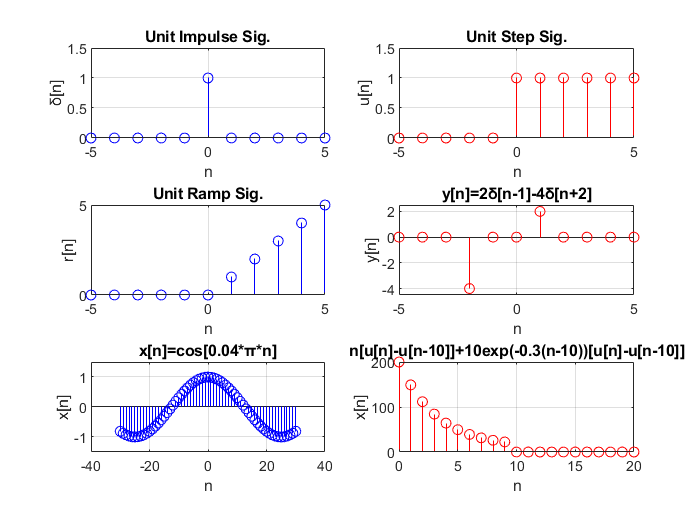

clc;
close;

sgtitle("1Q")

syms y(x)
y(x) = piecewise(x<0, 0, x==0, 1, x>0, 0);

t=(-5:1:5); 
subplot(3,2,1) % Allotting plot tile 1 of 3x2 tiles
stem(t,y(t),'b') % Discrete Time Plot of δ[n]
title("Unit Impulse Sig.") % Giving Plot Title
xlabel("n") % Assigning X-Label
ylabel("δ[n]") % Assigning Y-Label
ylim([0 1.5]) % Assigning Y-Limit
grid on % Enabling Grids

clc; % Clearing command window
clearvars; % Clearing all variables
syms y(x) % Creating a dynamic variable
y(x) = piecewise(x<0, 0, x==0, 1, x>0, 1);
% Piecewise definition of u[n]
t=(-5:1:5); % Initialising time range & time step
subplot(3,2,2) % Allotting plot tile 2 of 3x2 tiles
stem(t,y(t),'r') % Discrete Time Plot of u[n]
title("Unit Step Sig.") % Giving Plot Title
xlabel("n") % Assigning X-Label
ylabel("u[n]") % Assigning Y-Label
ylim([0 1.5]) % Assigning Y-Limit
grid on % Enabling Grids

clc; % Clearing command window
clearvars; % Clearing all variables
syms y(x) % Creating a dynamic variable
y(x) = piecewise(x<0, 0, x==0, 1, x>0, 1);
% Piecewise definition of u[n]
t=(-5:1:5); % Initialising time range & time step
r= t.*y(t); % Defining Unit Ramp Signal
subplot(3,2,3) % Allotting plot tile 3 of 3x2 tiles
stem(t,r,'b') % Discrete Time Plot of r[n]
title("Unit Ramp Sig.") % Giving Plot Title
xlabel("n") % Assigning X-Label
ylabel("r[n]") % Assigning Y-Label
grid on % Enabling Grids

clc; % Clearing command window
clearvars; % Clearing all variables
syms y(x) % Creating a dynamic variable
y(x) = piecewise(x<0, 0, x==0, 1, x>0, 0);
% Piecewise definition of δ[n]
t=(-5:1:5); % Initialising time range & time step
subplot(3,2,4) % Allotting plot tile 4 of 3x2 tiles
stem(t,(2*y(t-1)-4*y(t+2)),'r') % Discrete Time Plot of y[n]
title("y[n]=2δ[n-1]-4δ[n+2]") % Giving Plot Title
xlabel("n") % Assigning X-Label
ylabel("y[n]") % Assigning Y-Label
ylim([-4.5 2.5]) % Assigning Y-Limit
grid on % Enabling Grids

clc; % Clearing command window
clearvars; % Clearing all variables
t = (-30:1:30); % Initialising time range & time step
c = cos(0.04*pi*t); % Defining the cosine function
subplot(3,2,5) % Allotting plot tile 5 of 3x2 tiles
stem(t,c,"b") % Discrete Time Pot of x[n]
title("x[n]=cos[0.04*π*n]") % Giving Plot Title
xlabel("n") % Assigning X-Label
ylabel("x[n]") % Assigning Y-Label
ylim([-1.5 1.5]) % Assigning Y-Limit
grid on % Enabling Grids

clc; % Clearing command window
clearvars; % Clearing all variables
syms y(x) % Creating a dynamic variable
y(x) = piecewise(x<0, 0, x==0, 1, x>0, 1); % Piecewise definition of u[n]
t=(0:1:20); % Initialising time range & time step
f = y(t)-y(t-10); % Assigning u[n]-u[n-10] to a variable
subplot(3,2,6) % Allotting plot tile 6 of 3x2 tiles
stem(t,f.*(t+10*exp(-0.3*(t-10))),'r')
% Discrete Time Plot of x[n]
title("n[u[n]-u[n-10]]+10exp(-0.3(n-10))[u[n]-u[n-10]]")
% Giving Plot Title
xlabel("n") % Assigning X-Label
ylabel("x[n]") % Assigning Y-Label
grid on % Enabling Grids